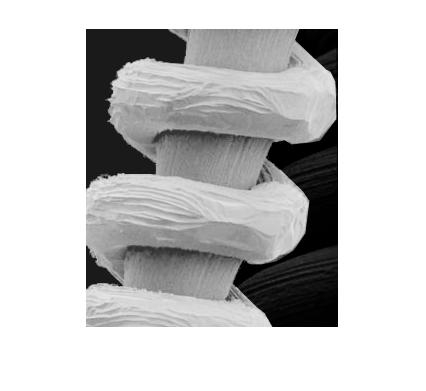

% ex312_LocalEnhance
%
% 2018.10, 解释中间步骤

close all
I = imread('..\data\Fig0327(a)(tungsten_original).tif');
figure(1),imshow(I),set(gcf,'name','Original');

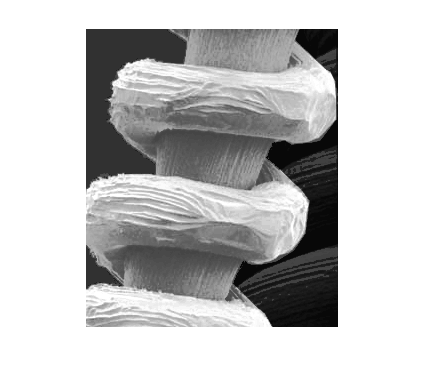

%% Global histogram equalization
J1 = histeq(I);
figure(2),imshow(J1),set(gcf,'name','Global histogram equalization');

%% Enhancement using local histogram statistics
I = double(I);
mean_global = mean2(I);
std_global = std2(I);

tic
fun1 = @(x) mean2(x);
mean_local_o = nlfilter(I,[3 3],fun1);% slow
toc

时间已过 1.237784 秒。


tic
newI = zeros(size(I) + [2 2]);
newI(2:end-1,2:end-1) = I;
intI = integralImage(newI);
H = integralKernel([1 1 3 3], 1/9);
mean_local = integralFilter(intI,H);
toc

时间已过 0.015050 秒。


max(max(abs(mean_local-mean_local_o)))

ans = 0

tic
fun2 = @(x) std2(x);
std_local_o = nlfilter(I,[3 3],fun2);% slow
toc

tic
std_local = stdfilt(newI);
std_local = std_local(2:end-1, 2:end-1);
toc
max(max(abs(std_local - std_local)))

figure(3),imshow(uint8(mean_local)),set(gcf,'name','Local mean');
figure(4),imshow(uint8(std_local)),set(gcf,'name','Local standard deviation');

%k0 = 0.4; k1 = 0.02; k2 = 0.4; E = 4; % 解释
k0 = 0.2; k1 = 0.001; k2 = 0.2; E = 2; % 解释
mask = (mean_local<=k0*mean_global) & (std_local>=k1*std_global) & (std_local<=k2*std_global);
J2 = I;
figure,imshow(mean_local<=k0*mean_global);
figure,imshow(std_local>=k1*std_global);
figure,imshow(std_local<=k2*std_global);
J2(mask) = I(mask)*E;
figure(5),imshow(mask),set(gcf,'name','MASK');
figure(6),imshow(uint8(J2)),set(gcf,'name','Enhancement by local statistics');